# **The heat equation**

## 1. Introduction

- Let's assume a 1-dimensional rod with length $L>0$ made of an isotropic material,

- The function $T(x,t)$ describes the heat of a point $x$ at time $t$, $x \in [ 0,L ]$, $t \in [0,\infty)$,

- At $t=0$, the rod has some initial heat distribution $T(x,0) = \phi(x)$,

- We assume no heat exchange with the enviornment.

Knowing that, is there a way to know how the heat distribution in the object changes over time? 

## 2. Joseph Fourier's study of heat flow

        *The Analytical Theory of Heat *(fr. *Théorie analytique de la chaleur*) is Fourier's 1822 publication of his work on heat flow. His work was based on Isaac Newton's law of cooling, which states:

*The rate of heat **loss of a body is directly proportional to the difference in the** temperatures **between the body and its environment.*

It is in this book where he famously stated, that any function can be expressed as an infinite sum of sine waves, which led to the invention of the fourier series and later, the fourier transform.


$$\frac{\partial T}{\partial t} = \alpha \cdot \frac{\partial^2 T}{\partial x^2$$


The heat equation for 1 dimension


$$\frac{\partial T}{\partial t} = \alpha \cdot \left( \frac{\partial^2 T}{\partial x^2}+\frac{\partial^2 T}{\partial y^2}+\frac{\partial^2 T}{\partial z^2} \right)$$


Let's first look at an example initial distribution $\phi (x)$

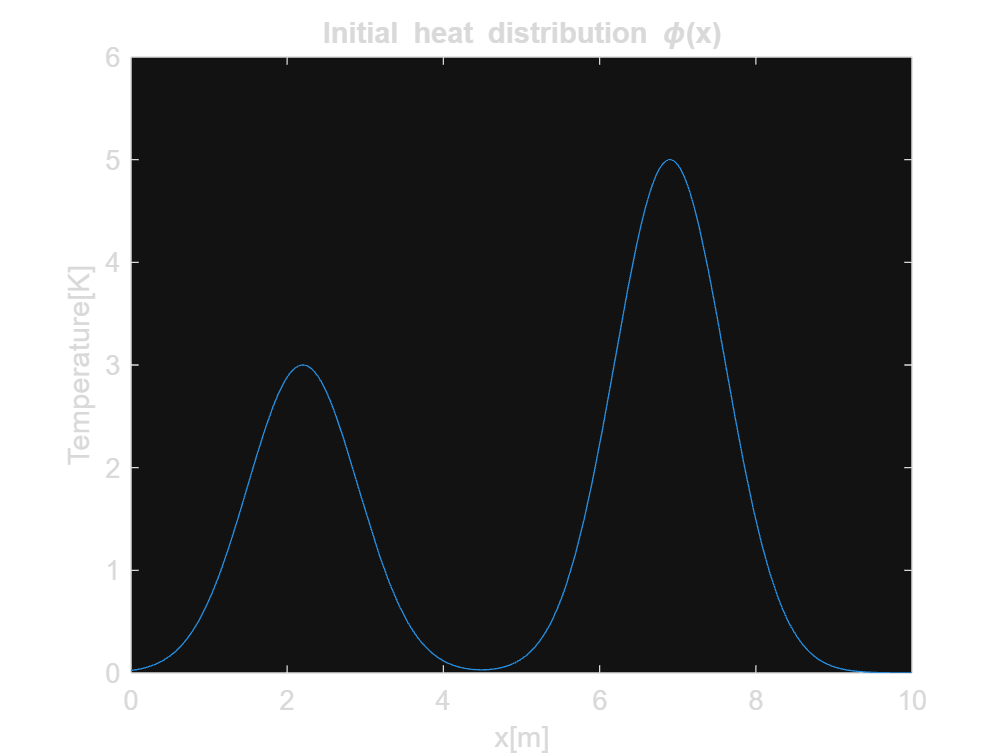

length = 10;
first_peak_middle =2.2;
second_peak_middle = 6.9;
first_peak_value = 3;
second_peak_value = 5;
syms x
assume(x,"positive")
phi(x) = first_peak_value*exp(-(x-first_peak_middle).^2)+second_peak_value*exp(-(x-second_peak_middle).^2);

figure(1)
grid on
fplot(phi, [0 length]);
xlim([0 length])
ylim([0 max(double(subs(phi,x,first_peak_middle)),double(subs(phi,x,second_peak_middle)))+1])
title("Initial heat distribution \phi(x)")
xlabel("x[m]")
ylabel("Temperature[K]")

## Select Solution Mesh

Use a spatial mesh of 20 points and a time mesh of 30 points. Since the solution rapidly reaches a steady state, the time points near $t=0$ are more closely spaced together to capture this behavior in the output. 

L = 10;
x = linspace(0,L,1000);
t = linspace(0,10,1000);

## Solve Equation

Finally, solve the equation using the symmetry $m$, the PDE equation, the initial condition, the boundary conditions, and the meshes for $x$ and $t$.

m = 0;
sol = pdepe(m,@heatpde,@heatic,@heatbc,x,t);

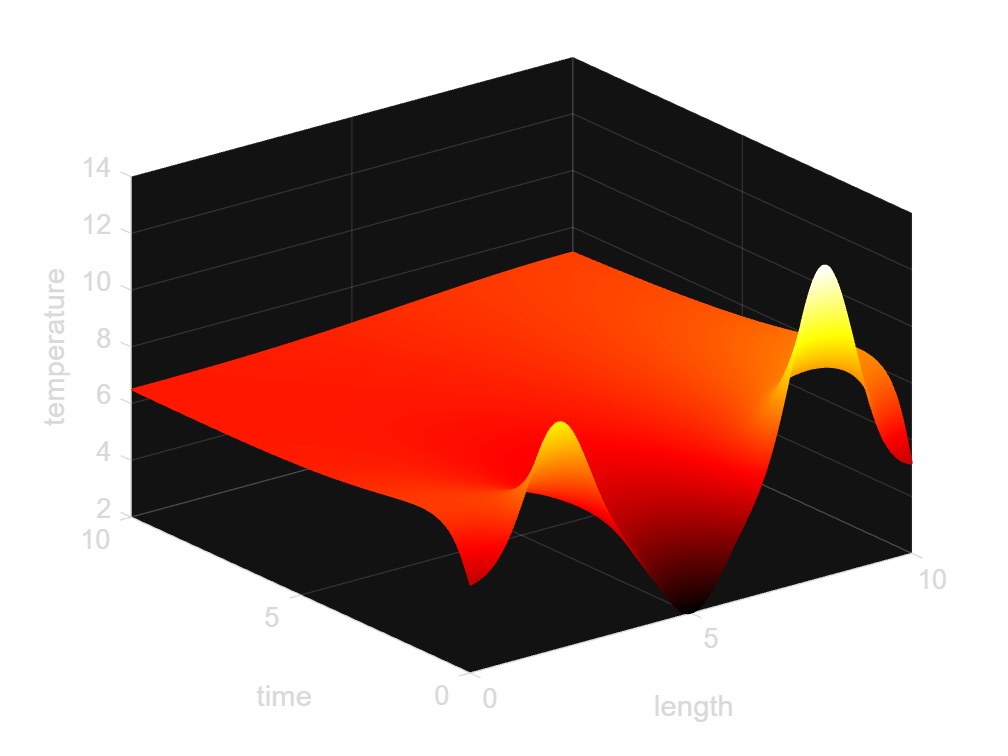

figure(2)
mesh(x,t,sol)
xlabel("length")
ylabel("time")
zlabel("temperature")
colormap("hot")

## Local Functions

function [c,f,s] = heatpde(x,t,u,dudx)
c = 1;
f = dudx;
s = 0;
end
function u0 = heatic(x)
u0 = 5*exp(-(x-2).^2) + 8*exp(-(x-8).^2) + 5 - 3 * exp(-(x-5).^2);
end
function [pl,ql,pr,qr] = heatbc(xl,ul,xr,ur,t)
pl = 0;
ql = 1;
pr = 0;
qr = 1;
end